Problem (3)

Student 1: Saachi Tamboli

Student 2: Brett Luthern

% Parameters

zetaP = 350; %km - perigee altitude
rp = 6371 + zetaP; % perigee radius
e = 0.1;
Omega = 195 * pi/180; %rad
i = 54 * pi/180; %rad
w = 235 * pi/180; %rad
ta = 20 * pi/180; %rad
muE = 3.986e5;
rE = 6371;

% logrithmic distibution
N = 30;

% ballistic
mu_bc = log(20);
sigma_bc = 0.5;

Part A:

a = rp/(1-e);

[r0, v0] = coe2rv(a, e, Omega, i, w, ta, muE);

% a) Code function [v, bc] = explosion(mu_v, sigma_v, mu_bc, sigma_bc)
function [v, bc] = explosion(mu_v, sigma_v, mu_bc, sigma_bc)
    N = 30;
    v = mu_v + sigma_v*randn(3,N);
    bc = lognrnd(mu_bc, sigma_bc, [1,N]);
end

[v0_debris, bc] = explosion(v0, 0.1, mu_bc, sigma_bc);

N = 30;
V = zeros(3, N);

for k = 1:N
    r0 = circshift(r0, [0 1]);   % rotate elements
    r0_debris(:,k) = r0.';
end

Part B:

% b) implement a function ap = drag_acceleration(zeta, v, bc)


function ap = drag_acceleration(zeta, v, bc)
    H = 50;
    rho0 = 1e-8;
    zeta0 = 100;
    if (zeta < zeta0)
        ap = NaN(3,1);
    else
        rho = rho0*exp(-(zeta-zeta0)/H);
        ap = ((-0.5 / norm(bc))* rho * norm(v)) .* v;
    end
end

Part C:

function ap = J2_acceleration(r)
    
J2 = 0.00108263;
    muE = 3.986e5;
    rE = 6371;
    
    x = r(1);
    y = r(2);
    z = r(3);

    rmag = norm(r);
    rz2 = (z/rmag)^2;

    factor = -(3/2)*J2*muE*rE^2 / rmag^5;

    ap = factor * [
        x*(1 - 5*rz2);
        y*(1 - 5*rz2);
        z*(3 - 5*rz2)
    ];

end

ap = J2_acceleration(r0);

Part D:

function [r, v] = cowell(r0, v0, bc, t, flag_drag, flag_J2)

    muE = 3.986e5;
    rE = 6371;

    function dy = eom(~, y, bc_i)
        rvec = y(1:3);
        vvec = y(4:6);
        rmag = norm(rvec);

        accel = -muE/rmag^3 * rvec;

        if flag_J2
            accel = accel + J2_acceleration(rvec);
        end

        if flag_drag
            zeta = rmag - rE;
            accel = accel + drag_acceleration(zeta, vvec, bc_i);
        end

        dy = [vvec; accel];
    end

    N = size(r0,2);
    M = length(t);

    r = NaN(3,N,M);
    v = NaN(3,N,M);

    for k = 1:N
        y0 = [r0(:,k); v0(:,k)];

        [Tsol, Y] = ode45(@(tt,y) eom(tt,y,bc(k)), t, y0);

        nk = length(Tsol);

        r(:,k,1:nk) = permute(Y(:,1:3), [2 3 1]);
        v(:,k,1:nk) = permute(Y(:,4:6), [2 3 1]);
    end
end

Part E:

% Time vector: 6 months, sampled every 7 days
dt_days = 7;
t_days = 0:dt_days:180;
t = t_days * 24 * 3600;

% Propagate: case (1) without perturbations
flag_drag = false;
flag_J2   = false;

[r, v] = cowell(r0_debris, v0_debris, bc, t, flag_drag, flag_J2);

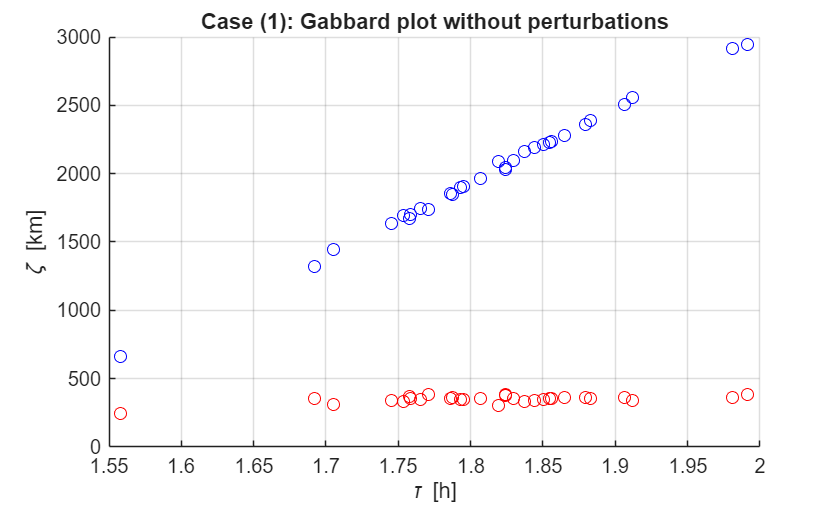


%% Extract orbital elements at each saved time
M = length(t);

a_hist     = NaN(N, M);
e_hist     = NaN(N, M);
Omega_hist = NaN(N, M);
zp_hist    = NaN(N, M);
za_hist    = NaN(N, M);
tau_hist   = NaN(N, M);

for k = 1:N
    for m = 1:M
        rk = r(:,k,m);
        vk = v(:,k,m);

        % Skip any bad trajectories
        if any(isnan(rk)) || any(isnan(vk))
            continue
        end

        [a,e,Omega,inc,omega,theta] = rv2coe(rk, vk);

        a_hist(k,m) = a;
        e_hist(k,m) = e;
        Omega_hist(k,m) = Omega;

        zp_hist(k,m) = a*(1-e) - rE;   % perigee altitude
        za_hist(k,m) = a*(1+e) - rE;   % apogee altitude
        tau_hist(k,m) = 2*pi*sqrt(a^3/muE)/3600;   % period in hours
    end
end

%% -----------------------
%% Plot 1: Gabbard plot
%% -----------------------
figure(1);
hold on;
grid on;

for m = 1:M
    plot(tau_hist(:,m), zp_hist(:,m), "ro");
    plot(tau_hist(:,m), za_hist(:,m), "bo");
end

xlabel('\tau [h]');
ylabel('\zeta [km]');
title('Case (1): Gabbard plot without perturbations');

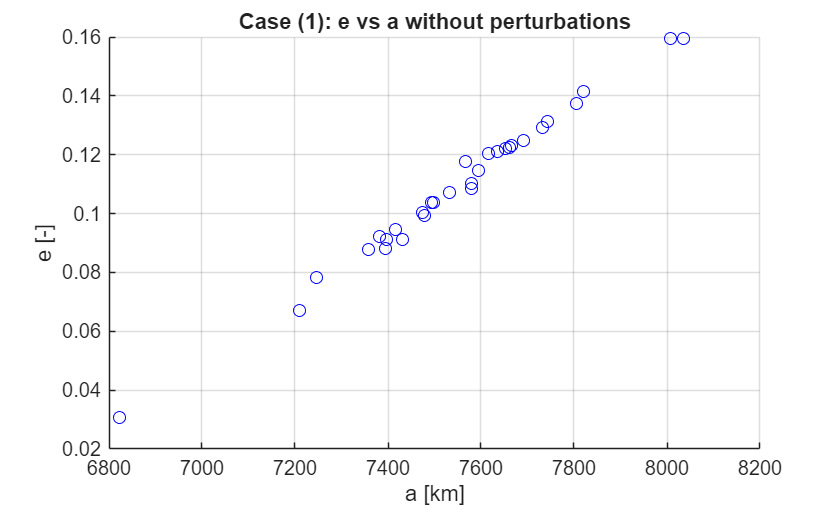


%% -----------------------
%% Plot 2: e vs a
%% -----------------------
figure(2);
hold on;
grid on;

for m = 1:M
    plot(a_hist(:,m), e_hist(:,m), "bo");
end

xlabel('a [km]');
ylabel('e [-]');
title('Case (1): e vs a without perturbations');

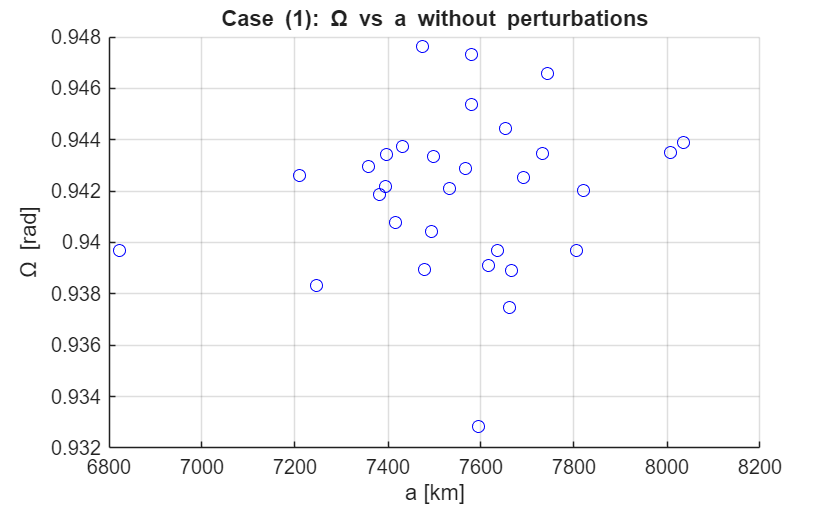


%% -----------------------
%% Plot 3: Omega vs a
%% -----------------------
figure(3);
hold on;
grid on;

for m = 1:M
    plot(a_hist(:,m), (Omega_hist(:,m)), "bo");
end

xlabel('a [km]');
ylabel('\Omega [rad]');
title('Case (1): \Omega vs a without perturbations');

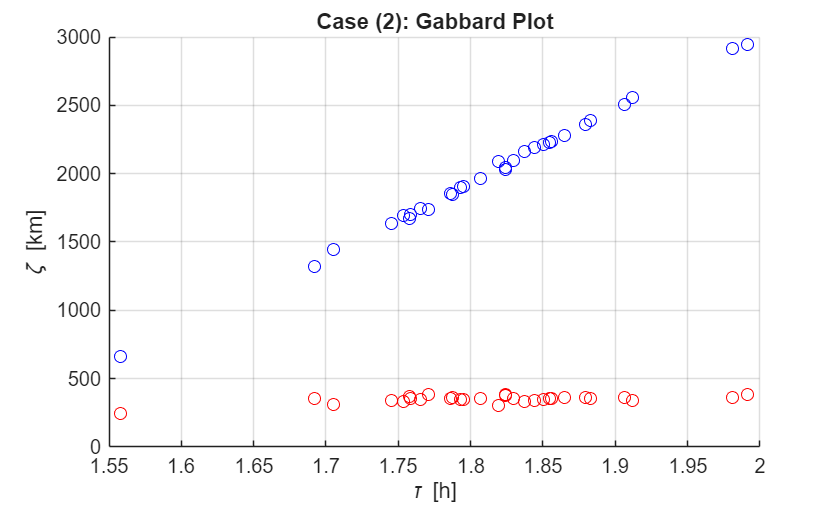

%% Case 2
% Time vector: 6 months, sampled every 7 days
% Propagate: case (1) without perturbations
flag_drag = true;
flag_J2 = false;

[r, v] = cowell(r0_debris, v0_debris, bc, t, flag_drag, flag_J2);

%% Extract orbital elements at each saved time
M = length(t);

a_hist = NaN(N, M);
e_hist = NaN(N, M);
Omega_hist = NaN(N, M);
zp_hist = NaN(N, M);
za_hist = NaN(N, M);
tau_hist = NaN(N, M);

for k = 1:N
    for m = 1:M
        rk = r(:,k,m);
        vk = v(:,k,m);

        % Skip any bad trajectories
        if any(isnan(rk)) || any(isnan(vk))
            continue
        end

        [a,e,Omega,inc,omega,theta] = rv2coe(rk, vk);

        a_hist(k,m) = a;
        e_hist(k,m) = e;
        Omega_hist(k,m) = Omega;

        zp_hist(k,m) = a*(1-e) - rE;   % perigee altitude
        za_hist(k,m) = a*(1+e) - rE;   % apogee altitude
        tau_hist(k,m) = 2*pi*sqrt(a^3/muE)/3600;   % period in hours
    end
end

%% -----------------------
%% Plot 1: Gabbard plot
%% -----------------------
figure(4);
hold on;
grid on;

for m = 1:M
    plot(tau_hist(:,m), zp_hist(:,m), "ro");
    plot(tau_hist(:,m), za_hist(:,m), "bo");
end

xlabel('\tau [h]');
ylabel('\zeta [km]');
title('Case (2): Gabbard Plot');

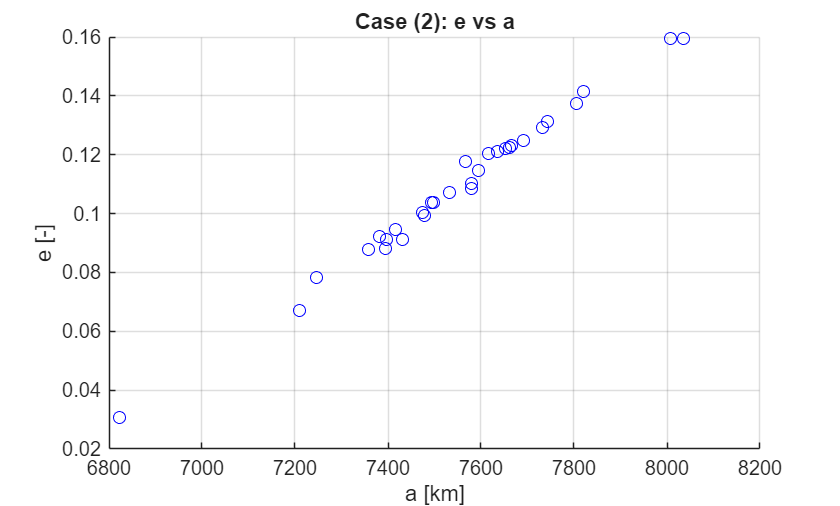


%% -----------------------
%% Plot 2: e vs a
%% -----------------------
figure(5);
hold on;
grid on;

for m = 1:M
    plot(a_hist(:,m), e_hist(:,m), "bo");
end

xlabel('a [km]');
ylabel('e [-]');
title('Case (2): e vs a');

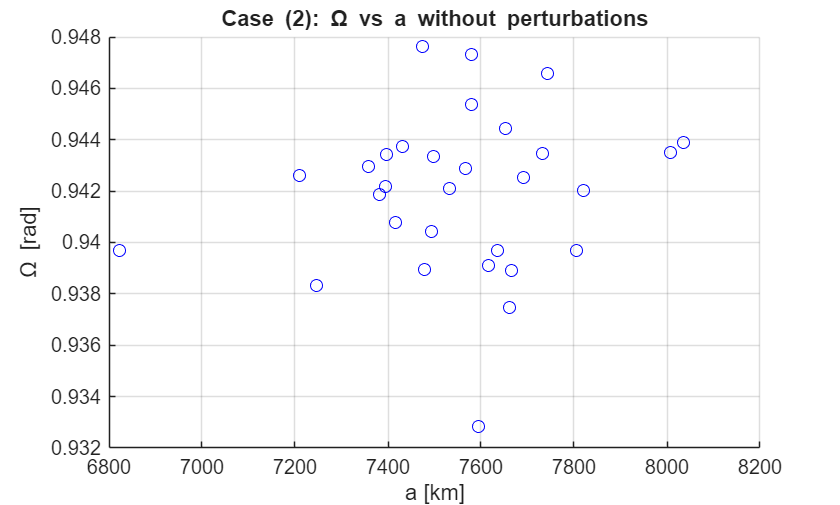


%% -----------------------
%% Plot 3: Omega vs a
%% -----------------------
figure(6);
hold on;
grid on;

for m = 1:M
    plot(a_hist(:,m), (Omega_hist(:,m)), "bo");
end

xlabel('a [km]');
ylabel('\Omega [rad]');
title('Case (2): \Omega vs a without perturbations');

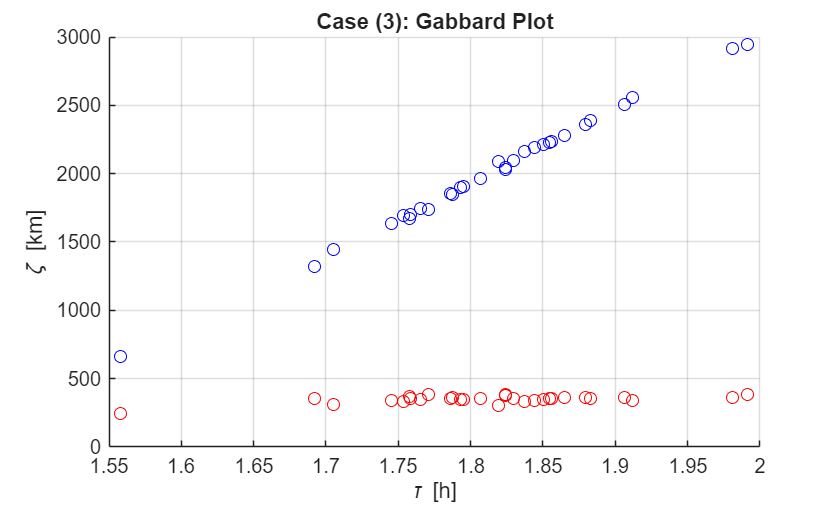

%% Case 3
% Propagate: case (1) without perturbations
flag_drag = true;
flag_J2 = true;

[r, v] = cowell(r0_debris, v0_debris, bc, t, flag_drag, flag_J2);

%% Extract orbital elements at each saved time
M = length(t);

a_hist = NaN(N, M);
e_hist = NaN(N, M);
Omega_hist = NaN(N, M);
zp_hist = NaN(N, M);
za_hist = NaN(N, M);
tau_hist = NaN(N, M);

for k = 1:N
    for m = 1:M
        rk = r(:,k,m);
        vk = v(:,k,m);

        % Skip any bad trajectories
        if any(isnan(rk)) || any(isnan(vk))
            continue
        end

        [a,e,Omega,inc,omega,theta] = rv2coe(rk, vk);

        a_hist(k,m) = a;
        e_hist(k,m) = e;
        Omega_hist(k,m) = Omega;

        zp_hist(k,m) = a*(1-e) - rE;   % perigee altitude
        za_hist(k,m) = a*(1+e) - rE;   % apogee altitude
        tau_hist(k,m) = 2*pi*sqrt(a^3/muE)/3600;   % period in hours
    end
end

%% -----------------------
%% Plot 1: Gabbard plot
%% -----------------------
figure(7);
hold on;
grid on;

for m = 1:M
    plot(tau_hist(:,m), zp_hist(:,m), "ro");
    plot(tau_hist(:,m), za_hist(:,m), "bo");
end

xlabel('\tau [h]');
ylabel('\zeta [km]');
title('Case (3): Gabbard Plot');

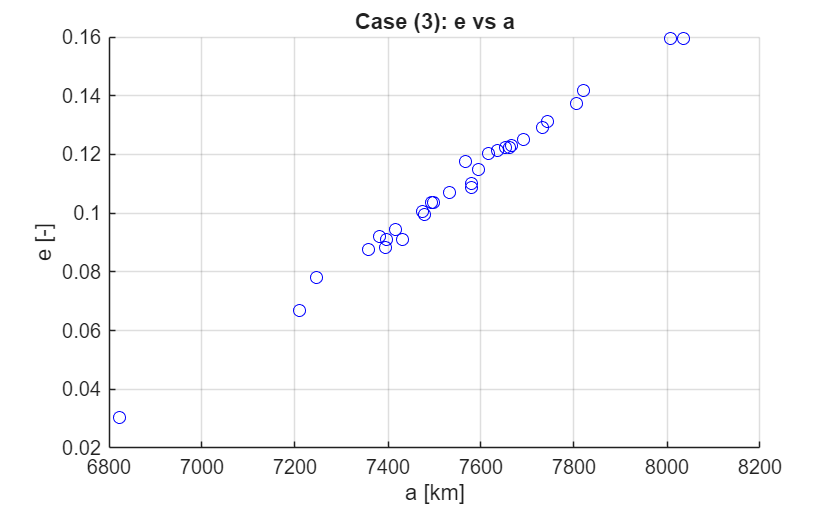


%% -----------------------
%% Plot 2: e vs a
%% -----------------------
figure(8);
hold on;
grid on;

for m = 1:M
    plot(a_hist(:,m), e_hist(:,m), "bo");
end

xlabel('a [km]');
ylabel('e [-]');
title('Case (3): e vs a');

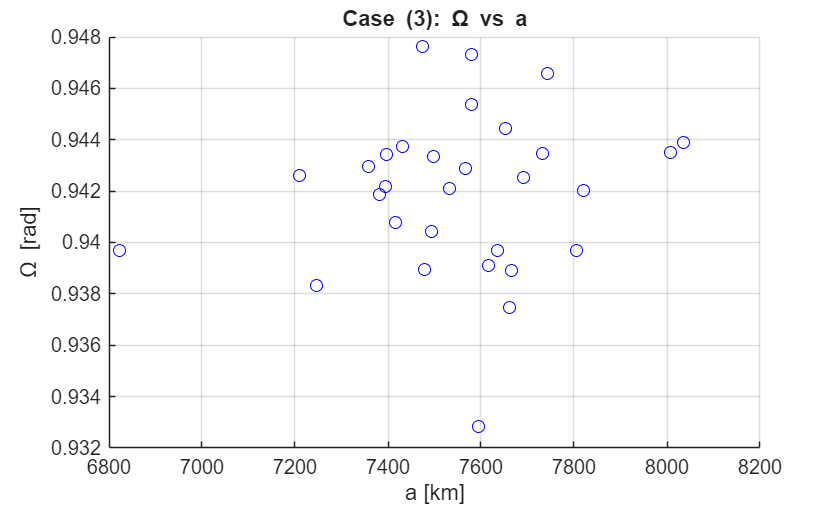


%% -----------------------
%% Plot 3: Omega vs a
%% -----------------------
figure(9);
hold on;
grid on;

for m = 1:M
    plot(a_hist(:,m), (Omega_hist(:,m)), "bo");
end

xlabel('a [km]');
ylabel('\Omega [rad]');
title('Case (3): \Omega vs a');